**Exercici 1.**

La lògica ens diu que derivar una imatge i després integrar-la ens deixaria la imatge original inalterada. Comproveu si és així al utilitzar dues finestres de convolució, una de derivativa i un altre integrativa.

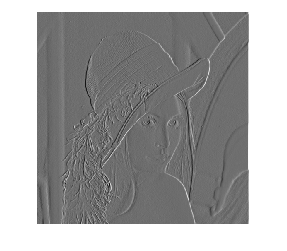

A = imread('lena_gray_512.tif');

dx = [1 -1];

Ader = imfilter(double(A), dx);

fdx = [1 1];
fdx = fdx / sum(sum(fdx));

AderInt = imfilter(Ader, fdx);

imshow(AderInt, [])

**Exercici 2.**

Enaltiu (*contour enhancement*) els contorns d’una imatge RGB. El resultat haurà de ser una imatge en nivells de gris combinant els tres canals.

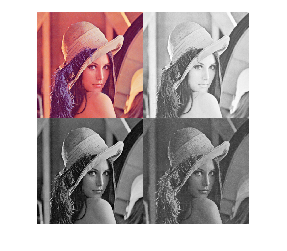

A = imread('lena_color_512.tif');

AR = A(:, :, 1);
AG = A(:, :, 2);
AB = A(:, :, 3);

montage({A AR AG AB})

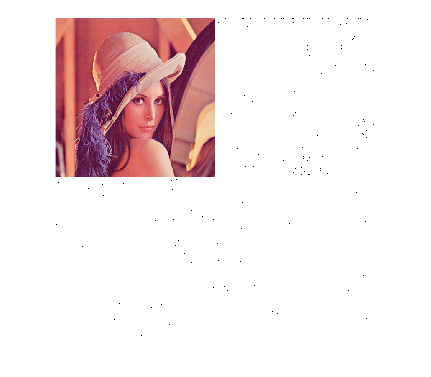


hx = [1 0 -1; 2 0 -2; 1 0 -1];
hy = hx';

dxR = imfilter(double(AR), hx);
dyR = imfilter(double(AR), hy);

dxG = imfilter(double(AG), hx);
dyG = imfilter(double(AG), hy);

dxB = imfilter(double(AB), hx);
dyB = imfilter(double(AB), hy);

contornR = abs(dxR) + abs(dyR);
contornG = abs(dxG) + abs(dyG);
contornB = abs(dxB) + abs(dyB);

montage({A, contornR, contornG, contornB})

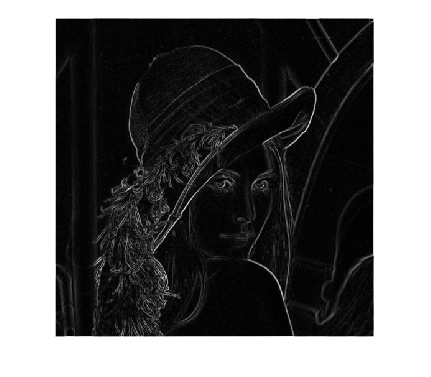


combinedContourns = abs(contornR) + abs(contornG) + abs(contornB);
imshow(combinedContourns, []);

**Exercici 3.**

Quant una part de la imatge està desenfocada presenta els contorns borrosos o suavitzats. En base a aquest fet, fer una funció que mesuri un possible valor l’enfoc en la part central d’una imatge. Així una imatge que  estigui més ben enfocada que un altre tindrà un valor superior. Proveu amb dues imatges extretes d’internet (cerqueu les paraules clau  *focus stacking*)

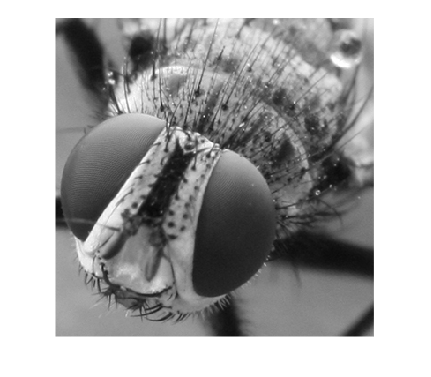

A = imread('Focus_stacking_Tachinid_fly.jpg');
A = rgb2gray(A);

sizes = size(A);
colsImage = sizes(2) / 3;

A1 = A(:, 1:colsImage, :);
A2 = A(:, colsImage+1:colsImage*2, :);

zoomSize = 0.35;

sizeA1 = size(A1);
rowsToGetA1 = sizeA1(1)*zoomSize : sizeA1(1)*(1-zoomSize);
colsToGetA1 = sizeA1(2)*zoomSize : sizeA1(2)*(1-zoomSize);
centreA1 = A1(rowsToGetA1, colsToGetA1, :);
imshow(centreA1);

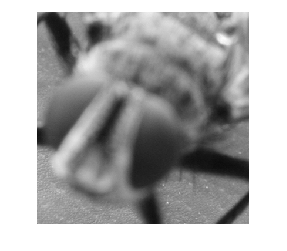


sizeA2 = size(A2);
rowsToGetA2 = sizeA2(1)*zoomSize : sizeA2(1)*(1-zoomSize);
colsToGetA2 = sizeA2(2)*zoomSize : sizeA2(2)*(1-zoomSize);
centreA2 = A2(rowsToGetA2, colsToGetA2, :);
imshow(centreA2);


hx = [1 0 -1; 2 0 -2; 1 0 -1];
hy = hx';

dx1 = imfilter(double(centreA1), hx);
dy1 = imfilter(double(centreA1), hy);

dx2 = imfilter(double(centreA2), hx);
dy2 = imfilter(double(centreA2), hy);

focusA1 = sum(sum(abs(dx1))) + sum(sum(abs(dy1)))

focusA1 = 11361686

focusA2 = sum(sum(abs(dx2))) + sum(sum(abs(dy2)))

focusA2 = 6051880


focusA1 / focusA2

ans = 1.8774

**Exercici 4.**

Suavitzar una imatge per després redimensionar-la a la meitat dona un millor aspecte visual que directament redimensionar-la a la meitat. Mesureu si la relació senyal soroll millora al fer aquest procés comparant amb el de directament redimensionat sense filtrar. Per fer-ho, torneu les imatges processades a la seva mida original i calculeu el SNR.

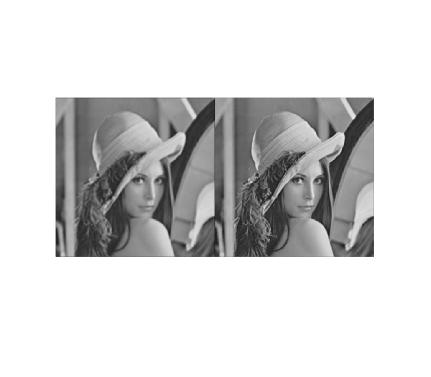

A = imread('lena_gray_512.tif');
zoomSize = 0.5;

filterSize = 5;
h = fspecial("gaussian", filterSize, filterSize/5);

A1 = imresize(A, zoomSize);
A1 = imfilter(A1, h);

A2 = imfilter(A, h);
A2 = imresize(A2, zoomSize);

A1res = imresize(A1, 1/zoomSize);
A2res = imresize(A2, 1/zoomSize);

montage({A1res, A2res})


D1 = A1res - A;
D2 = A2res - A;
SNR1 = sum(sum(A.*A)) / sum(sum(D1.*D1))

SNR1 = 10.7296

SNR2 = sum(sum(A.*A)) / sum(sum(D2.*D2))

SNR2 = 17.2032